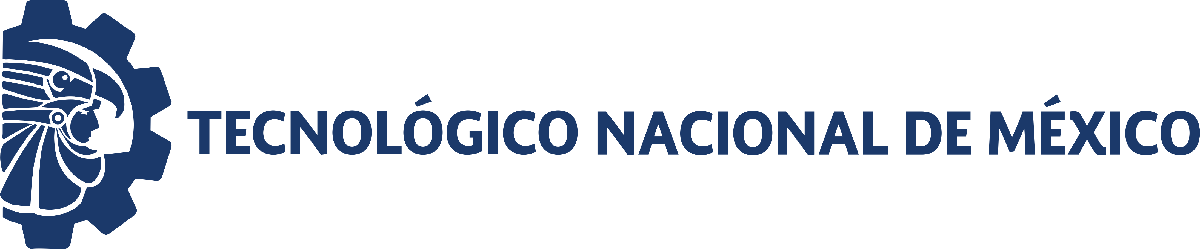                                 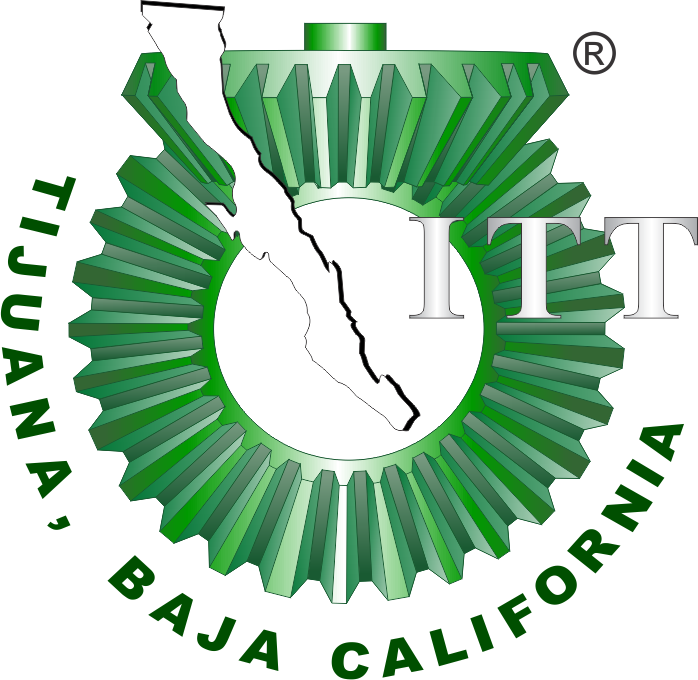

# Práctica cuatro: Modelado y control del sistema endócrino

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

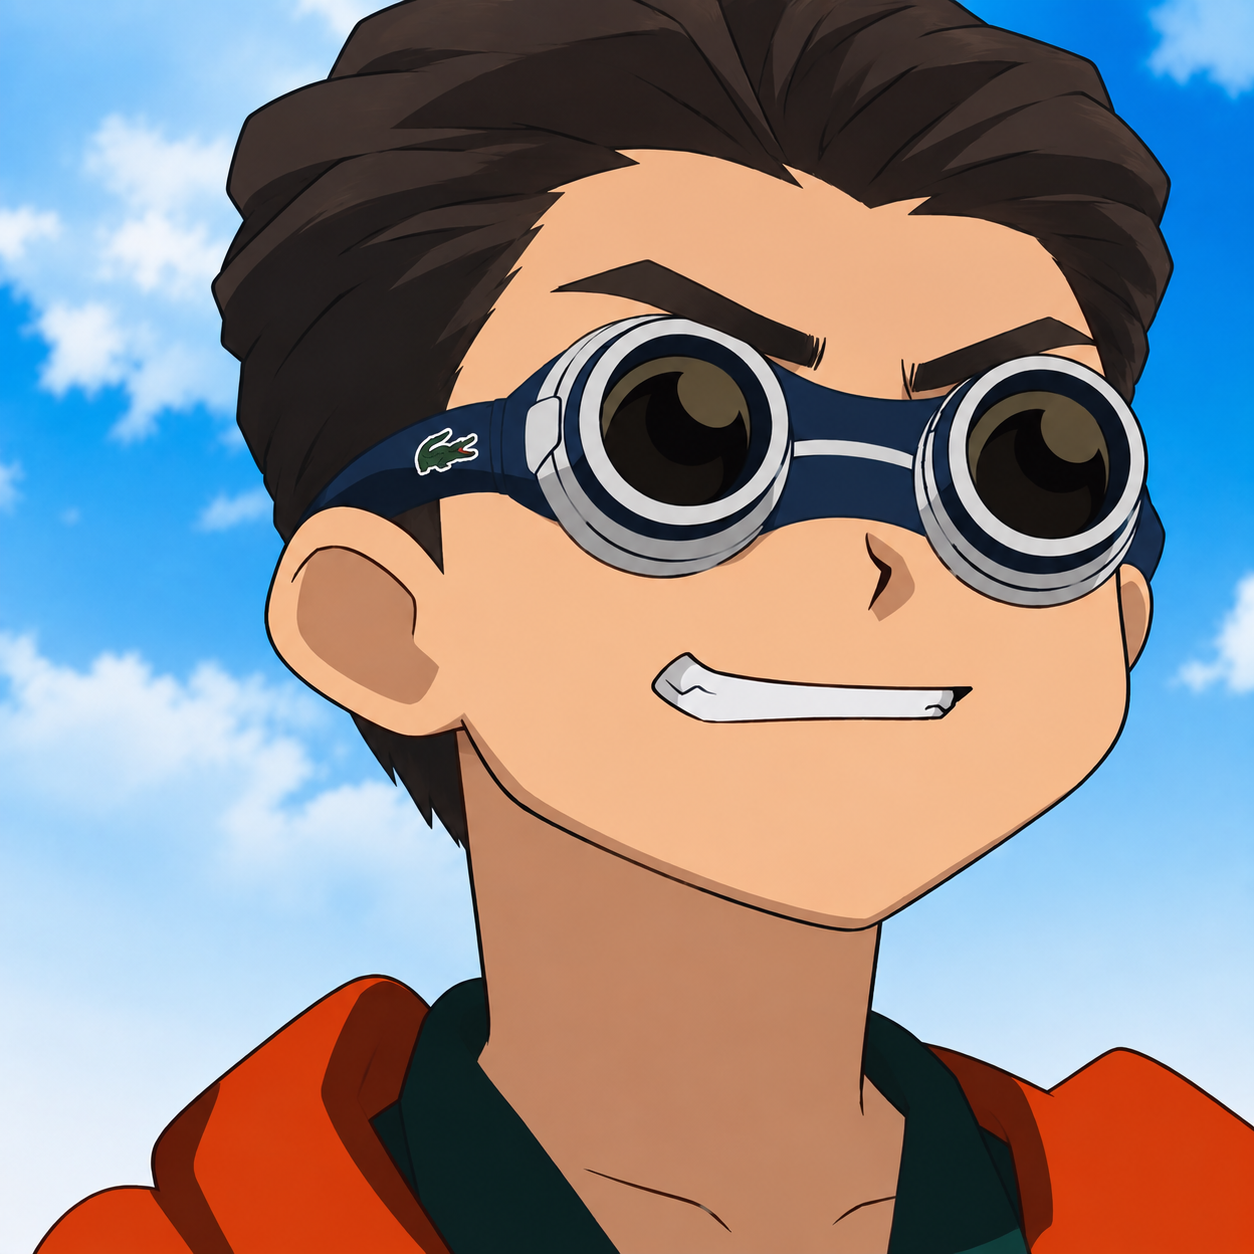

Nombre del alumno: **Gómez Quiroa Emiliano**

Número de control: **23212196**

Correo institucional: **l23212196@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('endocrino')
parameters.StopTime='15';
parameters.Solver='ode15s';
parameters.MaxStep='1e-3';
x=sim('endocrino',parameters);
t_data=(0:0.1:10)';
t=(0:0.001:10)';


## Gráfica

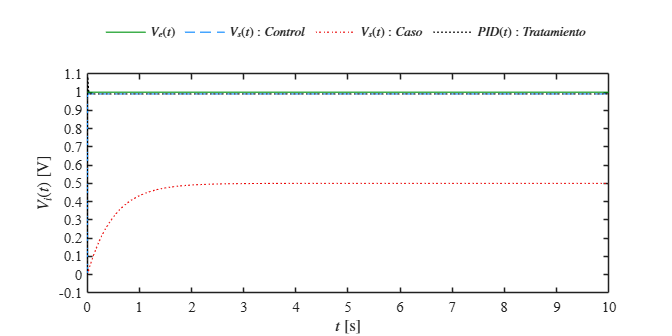


plotSignals(x.t,x.Ve,x.Control,x.Caso,x.PID,'Individual')

## Función: Respuesta de la simulación

function plotSignals(t,Ve,Control,Caso,PID,signal)
    set(figure(),'color','white')
    set(gcf,'units','inches','position',[1,1,7,3.5])
    set(gca,'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;

    clr1=[0, 148, 18]/255;
    clr2=[8, 135, 255]/255;
    clr3=[235, 9, 9]/255;
    clr4=[0, 0, 0]/255;
    order=[clr1;clr2;clr3;clr4]; colororder(order)
    
   

    if signal=="Individual"
        plot(t,Ve,'-',t,Control,'--',t,Caso,':',t,PID,':','LineWidth',.8,'MarkerSize',2.5,'MarkerIndices',...
            1:1e3:length(t));
        L=legend('$V_{e}(t)$','$V_s(t): Control$','$V_s(t): Caso$','$PID(t): Tratamiento$');
        set(L,'interpreter','latex','location','northoutside','orientation','horizontal','Box','off')
        
        xlabel('$t$ [s]','interpreter','latex')
        ylabel('$V_i(t)$ [V]','interpreter','latex')
        xlim([0 10]); xticks(0:1:10)
        ylim([0 1.1]); yticks(0:0.1:1.1)
    
    end

    exportgraphics(gcf,[signal,'_matlab.pdf'],'ContentType','vector')



end